# Controllo PID, PD e PD+comp. gravità

## Controllo PD

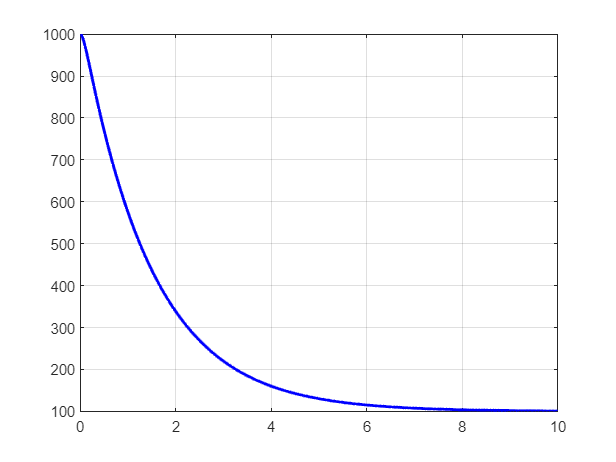

clear
clc
m = 1;
g0 = 10;
a = 0;

Kd = 1e5;
Ki = 0;
Kp = 1e1;

x0 = [1000; 0];
rif = [100; 0];

modello = @(t, x) modelloPM(t, x, m, rif, Kd, Kp, Ki, g0, a);

t0 = 0;
tf = 10;
tspan = [t0 tf];

[t, q] = ode45(modello, tspan, x0);

plot(t, q(:, 1), 'b', 'LineWidth', 2, 'DisplayName', 'quota');
grid on

## Controllo PID

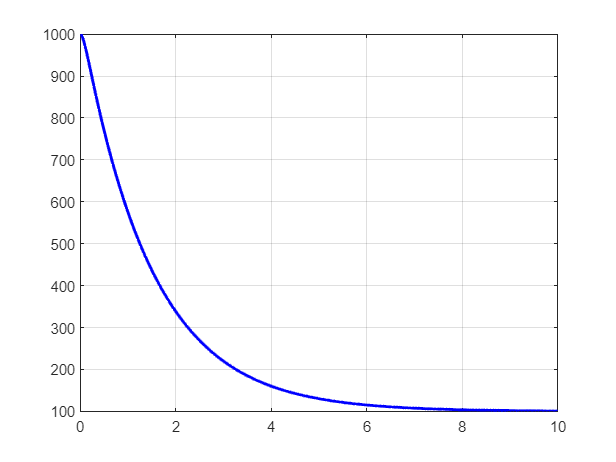

clear
clc
m = 1;
g0 = 10;
a = 0;

Kd = 1e5;
Ki = 1e1;
Kp = 2*m*Ki/Kd;

x0 = [1000; 0];
rif = [100; 0];

modello = @(t, x) modelloPM(t, x, m, rif, Kd, Kp, Ki, g0, a);

t0 = 0;
tf = 10;
tspan = [t0 tf];

[t, q] = ode45(modello, tspan, x0);

plot(t, q(:, 1), 'b', 'LineWidth', 2, 'DisplayName', 'quota');
grid on

## Controllo PD + compensazione gravità

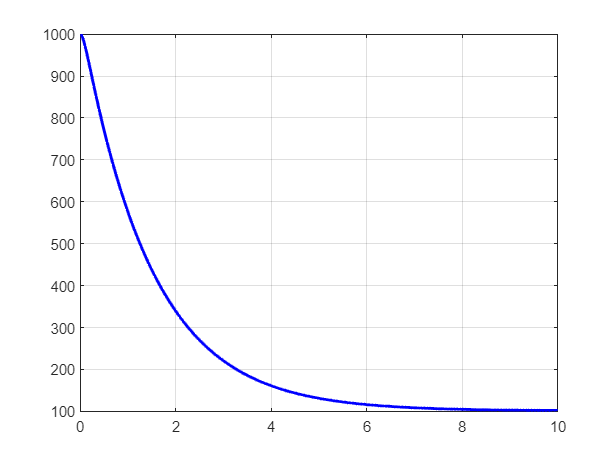

clear
clc
m = 1;
g0 = 10;
a = 1;

Kd = 1e5;
Ki = 0;
Kp = 1e1;

x0 = [1000; 0];
rif = [100; 0];

modello = @(t, x) modelloPM(t, x, m, rif, Kd, Kp, Ki, g0, a);

t0 = 0;
tf = 10;
tspan = [t0 tf];

[t, q] = ode45(modello, tspan, x0);

plot(t, q(:, 1), 'b', 'LineWidth', 2, 'DisplayName', 'quota');
grid on